# ForwardEuler_OscillatoryMotionLIVE.mlx

algorithm designed to plot max position for a harmonic oscillator as the step size is increased using the Forward Euler approximation approach.

## Define Parameters

iterations = 618;       % number of iterations in approximation 
m = 0.1;                % mass of object in motion [kg]
x0 = 0.1;               % initial position is at equilibirum
v0 = 0;                 % mass begins motion at rest
%dt = 0.001;            % step time inbetween point approximations
k = 10;                 % Spring constant [N/m]
T = (2*pi)*(m/k).^0.5;  % theoretical period
t = 0:((5*T)/618):5*T;  % time elapsed
x = ones(1,iterations); % intiialize position vector to store values
v = ones(1,iterations); % initialize velocity vector to store values
Xmaster = [];           % matrix to store x position at different step times
Vmaster = [];           % matrix to store velocity at different step times

## Calculations

x(1) = x0*x(1);             % set initial position
v(1) = v0*v(1);             % set initial velocity
j = 0;                      % set j to 0 to step through elements

%outer loop cycles through different time steps
for dt = 0.001:0.0001:T/10   % guarantees > 10 steps per period
    
    j = j+1;
    
    for i = (1:1:iterations)
        v(i+1) = v(i) - (k/m)*x(i).*dt; % Approximate velocity
        x(i+1) = x(i)+v(i).*dt;         % Approximate position 
    end
    
    % record data from particular dt trial:
    stepsize(j) = dt;

    max_pos(j) = max(x);
    
    Xmaster = [Xmaster; x];
    Vmaster = [Vmaster; v];
end

## Plotting

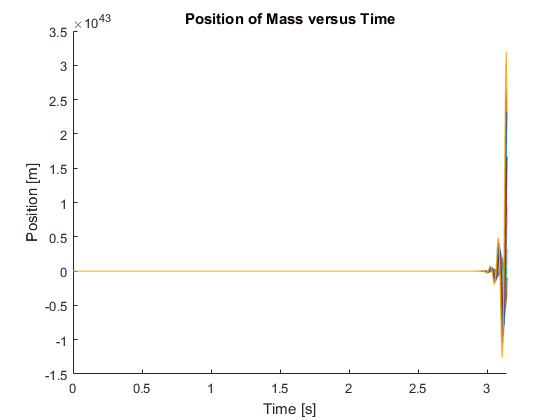

figure(1); hold on;                    % create first figure

title('Position of Mass versus Time'); % Label title
ylabel('Position [m]');                % Label y axis
xlabel('Time [s]');                    % Label x axis
xlim([0 (5*T)]);                       % set x limits

for i = 1:1:619
    plot(t,Xmaster(i,:))              
end

hold off;

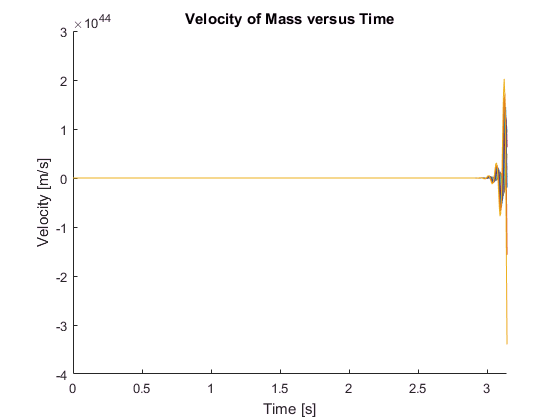


figure(2)                              % create second figure
hold on;

title('Velocity of Mass versus Time'); % Label title
ylabel('Velocity [m/s]');              % Label y axis
xlabel('Time [s]');                    % Label x axis
xlim([0 (5*T)]);                       % set x limits

for i = 1:1:619
    plot(t,Vmaster(i,:))              
end

hold off;                          

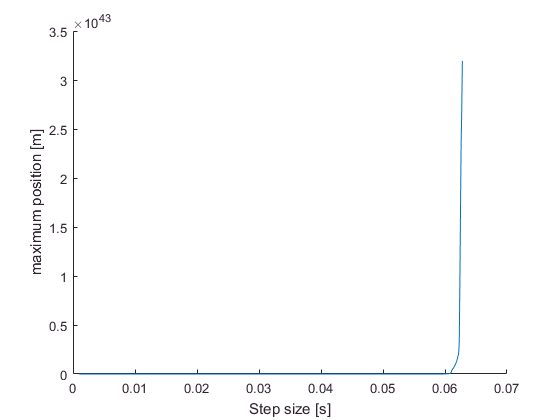


figure(3)                            % create third figure
hold on;

title('Max position vs Step Size');

plot(stepsize,max_pos);              % plot max position vs step time

ylabel('maximum position [m]');      % Label y axis
xlabel('Step size [s]');             % Label x axis

hold off;